# **Contact Time Calculation From Maximum Elevation Angle**

**Hongseok Kim, UT Austin**

## I. Orbital Kinematics of SSO satellite

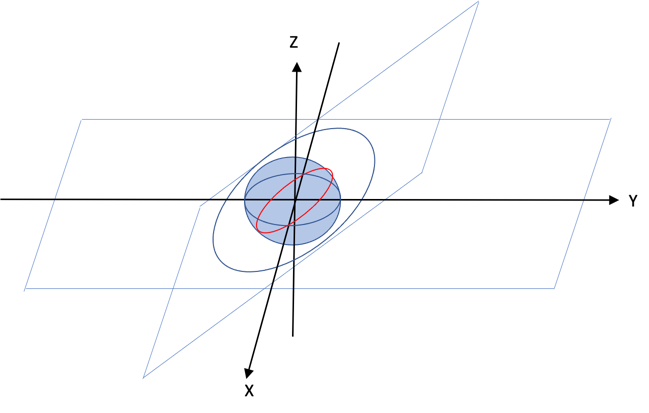

Suppose the ECI frame is on XYZ cartesian coordinate. The satellite orbit trajectory is stable in this frame.

- We alreay have satellite height(600km) and earth radious information, so all we have to choose is inclination angle $i$.

- In this coordinate, suppose the radious of orbital circle is 1 for simple calculation.

- Also, given the satellite hight, we can calculate the satellite's velocity and orbital period.

            
$$\begin{array}{l}
\textrm{flight}\;\textrm{velocity}:v=\sqrt[]{\frac{398600\ldotp 5}{6378\ldotp 14+h}}\left(\textrm{km}/s\right)\;\;\;\;\;\;,\textrm{orbital}\;\textrm{period}:\;P=2\pi \frac{\;6378\ldotp 14+h}{v}\left(\sec \right)\\
\textrm{if}\;h=600\;\textrm{km}\to \;v=7\ldotp 5579\textrm{km}/s\;,P=5801\ldotp 23\;\textrm{Sec}\;=\;1:36:41\ldotp 23\;\left(\textrm{hh}:\textrm{mm}:\textrm{ss}\right)\;\;
\end{array}$$


Therefore, we can express the orbital trajectory as follows.

            
$$\begin{array}{l}
\textrm{Satellite}\;\textrm{trajectory}\;\left(x,y,z\right)\;\textrm{at}\;\textrm{ECI}\;\textrm{frame}\\
\left(x,y,z\right)=\left(\cos \;\theta ,\cos \;i\;\sin \;\theta ,\sin \;i,\sin \;\theta \right),\;\;\theta =\frac{2\pi t}{P},i=\textrm{inclination}\;\textrm{angle}\;\left(-\frac{\pi }{2}\le i\le \frac{\pi }{2}\right)\\
\left(x,y,z\right)=\left(\cos \;\frac{2\pi t}{P},\cos \;i\;\sin \;\frac{2\pi t}{P},\sin \;i\;\sin \;\frac{2\pi t}{P}\right)
\end{array}$$


For changing from ECI frame to ECF frame, we should consider the rotation of earth.

- Suppose the direction of satellit rotation and earth rotation is same , +Z rotation (counterclockwise)

- The earth rotation period is known: $P_E =23:56:4\ldotp 09\;\left(\textrm{hh}:\textrm{mm}:\textrm{ss}\right)$

            
$$\begin{array}{l}
\textrm{Satellite}\;\textrm{trajectory}\;\left(x,y,z\right)\;\textrm{at}\;\textrm{ECF}\;\textrm{frame}\\
\;z\;\textrm{remains}\;\textrm{same},\;z=\sin \;i\;\sin \;\frac{2\pi t}{P}\\
\left\lbrack \begin{array}{c}
x\\
y
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
\cos \frac{2\pi t\;}{P_E } & \sin \frac{2\pi t\;}{P_E }\\
-\sin \frac{2\pi t\;}{P_E } & \cos \frac{2\pi t\;}{P_E }
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
\cos \;\frac{2\pi t}{P}\\
\cos \;i\;\sin \;\frac{2\pi t}{P}
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
\cos \frac{2\pi t\;}{P_E }\cos \;\frac{2\pi t}{P}\;+\sin \frac{2\pi t\;}{P_E }\;\cos \;i\;\sin \;\frac{2\pi t}{P}\\
-\sin \frac{2\pi t\;}{P_E }\cos \;\frac{2\pi t}{P}+\cos \frac{2\pi t\;}{P_E }\;\cos \;i\;\sin \;\frac{2\pi t}{P}
\end{array}\right\rbrack \\
\textrm{Therefore},\left\lbrack \begin{array}{c}
x\\
y\\
z
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
\cos \frac{2\pi t\;}{P_E }\cos \;\frac{2\pi t}{P}\;+\cos \;i\;\sin \frac{2\pi t\;}{P_E }\sin \;\frac{2\pi t}{P}\\
-\sin \frac{2\pi t\;}{P_E }\cos \;\frac{2\pi t}{P}+\cos \;i\;\cos \frac{2\pi t\;}{P_E }\;\sin \;\frac{2\pi t}{P}\\
\sin \;i\;\sin \;\frac{2\pi t}{P}
\end{array}\right\rbrack 
\end{array}$$


We can get the graph of basic trajectories.

i = 97.8/180*pi();
t_end = 1000;
h = 500;

v = sqrt(398600.5/(6378.14 + h));
P = 2 * pi() * (6378.14+h) / v;


r_E = 6378.14;
t = 0:0.1:t_end;
P_E = 23 * 3600 + 56 * 60 + 4.09;



x_ECI_x = cos(2*pi()*t/P);
x_ECI_y = cos(i)* sin(2*pi()*t/P);
x_ECI_z = sin(i)* sin(2*pi()*t/P);


x_ECF_x = cos(2*pi().*t/P_E).*cos(2*pi()*t/P) + cos(i).* sin(2*pi()*t/P_E) .* sin(2*pi()*t/P);
x_ECF_y = -sin(2*pi().*t/P_E).*cos(2*pi()*t/P) + cos(i).* cos(2*pi()*t/P_E) .* sin (2*pi()*t/P);
x_ECF_z = sin(i) * sin(2*pi()*t/P);


%plot3(x_ECI_x, x_ECI_y, x_ECI_z);
%plot3(x_ECF_x,x_ECF_y,x_ECF_z);
%plot(x_ECF_x,x_ECF_z);

### II. Calculating Elevation angle

We can express the position relationship by ground station and satellite by following diagram.

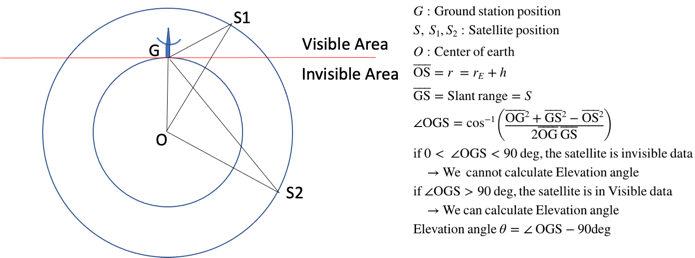

From Slant Range to Elevation Angle

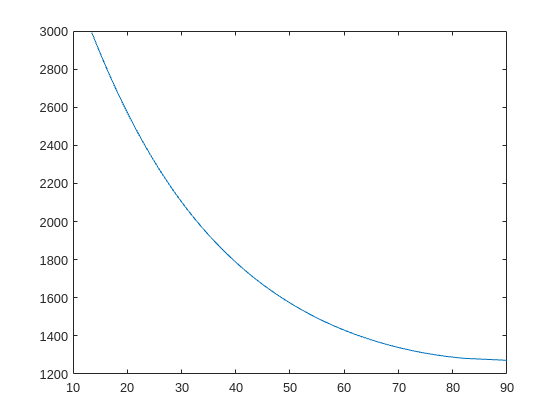

s = 1272:10:3000;
og = 6378.14;
os = 6378.14 + 1272;
elev_plus_90 = acos((og^2 + s.^2 - os.^2)./(2.*og.*s));
elev_angle = elev_plus_90*180/pi() - 90;
%plot(s,elev_angle)
plot(elev_angle,s)

## III. Calculating Contact Time From Maximum Elevation angle

In our SSO orbit satellite case,


$$\begin{array}{l}
\bar{\textrm{OG}} =r_E =6378\ldotp 14\textrm{km}\\
\bar{\textrm{OS}} =r_E +h=6978\ldotp 14\textrm{km}\\
\textrm{We}\;\textrm{should}\;\textrm{find}\;\bar{\textrm{GS}\;} \textrm{by}\;\textrm{calculating}\;\textrm{distance}\;\textrm{in}\;\textrm{ECF}\;\textrm{frame}
\end{array}$$


In the ECF frame, let G is at latitude = $\phi =36\degree \;21\prime 03″N$, which is the position of Daejeon, Korea, longitude = $\theta$, and assume G is on XZ plane.

Then we can get the position data of G, $G\left(x,y,z\right)=\left(r\;\cos \;\phi \;\cos \;\theta ,r\;\cos \;\phi \;\sin \;\theta ,r\;\sin \;\phi \right)$

From, $S\left(x,y,z\right)$at ECF frame we have got, we can calculate the length of $\bar{\textrm{GS}}$

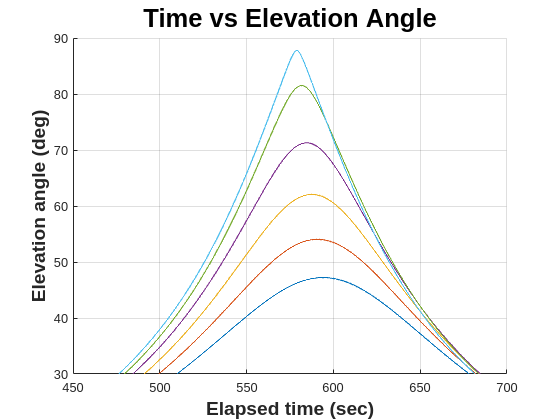


n = (-11 - (-5))/0.1+1;
data = zeros(n,2);
k = 1;

figure;
hold on
for theta_trans = -13:1:-8

% theta = -8.3/180*pi();
theta = theta_trans/180*pi();
phi = (36 + 21/60 + 3/3600)/180*pi();

G_x = r_E * cos(phi) * cos(theta);
G_y = r_E * cos(phi) * sin(theta);
G_z = r_E * sin(phi);


GS = sqrt(((r_E+h) * x_ECF_x - G_x).^2+((r_E+h) * x_ECF_y - G_y).^2+((r_E+h) * x_ECF_z - G_z).^2);
OGS_rad = acos((r_E^2+ GS.^2 -(r_E+h)^2)./(2.*r_E.*GS));
OGS_deg = OGS_rad/pi()*180;
elev = OGS_deg - 90;
elev_mat = [t',elev'];
elev_filtered = elev_mat(elev_mat(:,2)>=30,:);
plot(elev_filtered(:,1), elev_filtered(:,2),'LineWidth',1)
end

hold off
xlabel('Elapsed time (sec)','FontSize',15,'FontWeight','bold')
ylabel('Elevation angle (deg)','FontSize',15,'FontWeight','bold')
grid on
title('Time vs Elevation Angle','FontSize',20,'FontWeight','bold')

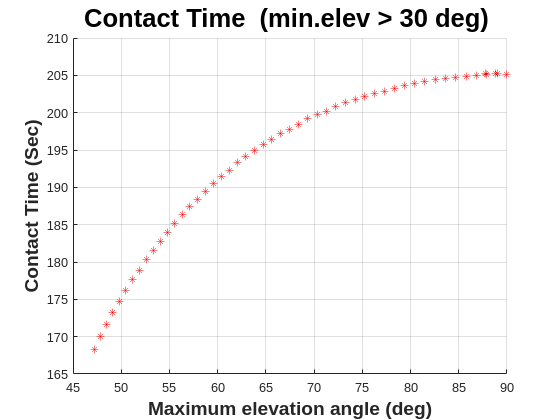


for theta_input = -13:0.1:-8



theta = theta_input/180*pi();
phi = (36 + 21/60 + 3/3600)/180*pi();

G_x = r_E * cos(phi) * cos(theta);
G_y = r_E * cos(phi) * sin(theta);
G_z = r_E * sin(phi);


GS = sqrt(((r_E+h) * x_ECF_x - G_x).^2+((r_E+h) * x_ECF_y - G_y).^2+((r_E+h) * x_ECF_z - G_z).^2);
OGS_rad = acos((r_E^2+ GS.^2 -(r_E+h)^2)./(2.*r_E.*GS));
OGS_deg = OGS_rad/pi()*180;
elev = OGS_deg - 90;

% plot(t, elev)


observe_boundary = find(elev > 30);
T_min = min(observe_boundary);
T_max = max(observe_boundary);
elev_max = max(elev);
duration = (T_max-T_min)/10;
data(k,1) = elev_max;
data(k,2) = duration;
k = k+1;

end

figure;
scatter(data(:,1),data(:,2),'red','*')
title('Contact Time  (min.elev > 30 deg) ','FontSize',20,'FontWeight','bold')
xlabel('Maximum elevation angle (deg)','FontSize',15,'FontWeight','bold')
ylabel('Contact Time (Sec)','FontSize',15,'FontWeight','bold')
grid on

## V. Calculate Energy Transmission Efficiency in Single Contact

theta = -8.3/180*pi();


phi = (36 + 21/60 + 3/3600)/180*pi();

G_x = r_E * cos(phi) * cos(theta);
G_y = r_E * cos(phi) * sin(theta);
G_z = r_E * sin(phi);


GS = sqrt(((r_E+h) * x_ECF_x - G_x).^2+((r_E+h) * x_ECF_y - G_y).^2+((r_E+h) * x_ECF_z - G_z).^2);
OGS_rad = acos((r_E^2+ GS.^2 -(r_E+h)^2)./(2.*r_E.*GS));
OGS_deg = OGS_rad/pi()*180;


total_received_energy = 0;

elev = OGS_deg - 90;
elev = elev(elev>=30);
t = 1:length(elev);
t = t/10;
P_received_vec = zeros(length(elev),1);


for i = 1:length(elev)

r_earth = 6378.14*10^3; %earth radius in m
h = 500*10^3; %altitude in m
%frequency
f = 5.8*10^9; %in 
%Wavelength
lambda = 299792458/(f); %in 1/m
%Power Added Efficiency
eff_PAE = .79;
%Antenna Efficiency
eff_ant = 0.856; %(max) around 0.55-.75
%diameter of Rectenna
d_r = 50;
%Area of Rectenna
A_r = pi*(d_r/2).^2;
%diameter of antenna
d_t = 3.75;
%Rectenna Efficiency (from tech papers)
eff_rec = 0.80;
%eff
eff_BCE = eff_PAE*eff_ant*eff_rec*(0.86*(1-exp(-1.1*(sqrt(((pi*(d_t/2).^2)*eff_ant)*A_r)./(lambda*(sqrt(r_earth^2+(r_earth+h).^2-2.*r_earth.*(r_earth+h).*cosd(90-elev(i)))))).^2)));

%Power input into transmission from energy acquisition analysis
P_solar = 6.74*10^5;
P_received = P_solar*eff_BCE;
P_received_vec(i) = P_received;


total_received_energy = total_received_energy + P_received * 0.1;

end

total_received_energy

total_received_energy = 145.8700

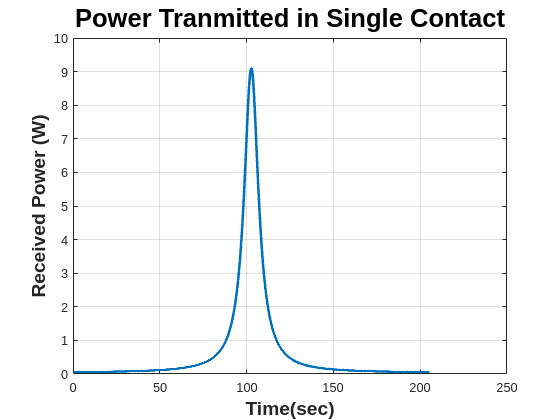


figure;
plot(t,P_received_vec,'LineWidth',2)
title('Power Tranmitted in Single Contact','FontSize',20,'FontWeight','bold')
ylabel('Received Power (W)','FontSize',15,'FontWeight','bold')
xlabel('Time(sec)','FontSize',15,'FontWeight','bold')
grid on

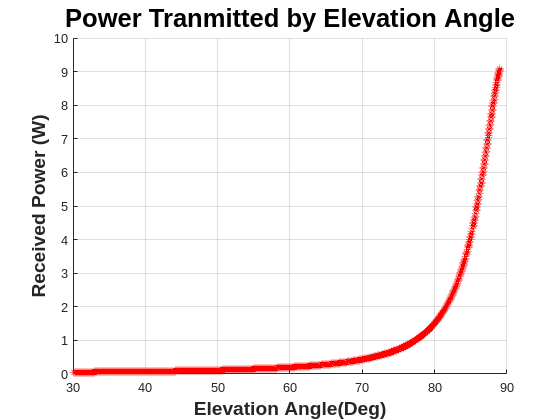


figure;
scatter(elev, P_received_vec,'r','*')
title('Power Tranmitted by Elevation Angle','FontSize',20,'FontWeight','bold')
ylabel('Received Power (W)','FontSize',15,'FontWeight','bold')
xlabel('Elevation Angle(Deg)','FontSize',15,'FontWeight','bold')
grid on

## V. Calculate Total Energy Transmitted in Single Contact

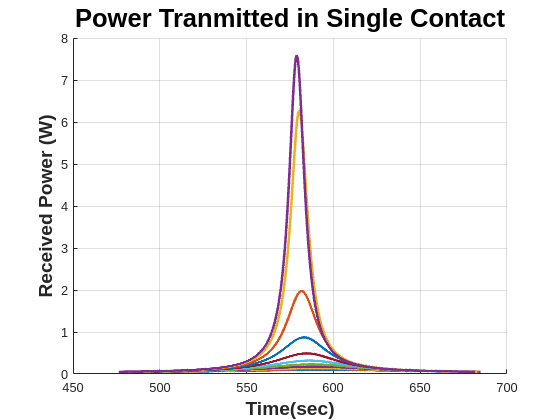

clear all;

i = 97.8/180*pi();
t_end = 1000;
h = 500;

v = sqrt(398600.5/(6378.14 + h));
P = 2 * pi() * (6378.14+h) / v;

r_E = 6378.14;
t = 0:0.1:t_end;
P_E = 23 * 3600 + 56 * 60 + 4.09;



x_ECI_x = cos(2*pi()*t/P);
x_ECI_y = cos(i)* sin(2*pi()*t/P);
x_ECI_z = sin(i)* sin(2*pi()*t/P);


x_ECF_x = cos(2*pi().*t/P_E).*cos(2*pi()*t/P) + cos(i).* sin(2*pi()*t/P_E) .* sin(2*pi()*t/P);
x_ECF_y = -sin(2*pi().*t/P_E).*cos(2*pi()*t/P) + cos(i).* cos(2*pi()*t/P_E) .* sin (2*pi()*t/P);
x_ECF_z = sin(i) * sin(2*pi()*t/P);


t = 0:0.1:1000;

ii = 1;


max_elevation_angle = zeros(length(-13:0.5:-8),1);
total_received_energy_vec = zeros(length(-13:0.5:-8),1);
figure;
hold on;

for theta_trans = -13:0.5:-8

theta = theta_trans/180*pi();
phi = (36 + 21/60 + 3/3600)/180*pi();

G_x = r_E * cos(phi) * cos(theta);
G_y = r_E * cos(phi) * sin(theta);
G_z = r_E * sin(phi);


GS = sqrt(((r_E+h) * x_ECF_x - G_x).^2+((r_E+h) * x_ECF_y - G_y).^2+((r_E+h) * x_ECF_z - G_z).^2);
OGS_rad = acos((r_E^2+ GS.^2 -(r_E+h)^2)./(2.*r_E.*GS));
OGS_deg = OGS_rad/pi()*180;
elev = OGS_deg - 90;
elev_mat = [t',elev'];
elev_filtered = elev_mat(elev_mat(:,2)>=30,:);
max_elevation_angle(ii) = max(elev_filtered(:,2));
P_received_vec = zeros(length(elev_filtered),1);

total_received_energy = 0;
for i = 1:length(elev_filtered)

r_earth = 6378.14*10^3; %earth radius in m
h_sim = 500*10^3; %altitude in m
%frequency
f = 5.8*10^9; %in 
%Wavelength
lambda = 299792458/(f); %in 1/m
%Power Added Efficiency
eff_PAE = .79;
%Antenna Efficiency
eff_ant = 0.856; %(max) around 0.55-.75
%diameter of Rectenna
d_r = 50;
%Area of Rectenna
A_r = pi*(d_r/2).^2;
%diameter of antenna
d_t = 3.75;
%Rectenna Efficiency (from tech papers)
eff_rec = 0.80;
%eff
eff_BCE = eff_PAE*eff_ant*eff_rec*(0.86*(1-exp(-1.1*(sqrt(((pi*(d_t/2).^2)*eff_ant)*A_r)/(lambda*(sqrt(r_earth^2+(r_earth+h_sim).^2-2.*r_earth.*(r_earth+h_sim).*cosd(90-elev_filtered(i,2)))))).^2)));
%Power input into transmission from energy acquisition analysis
P_solar = 675200;
P_received = P_solar*eff_BCE;
P_received_vec(i) = P_received;
total_received_energy = total_received_energy + P_received * 0.1;
end

plot(elev_filtered(:,1),P_received_vec,'LineWidth',2)

total_received_energy_vec(ii) = total_received_energy;
ii = ii+1;
end

hold off
title('Power Tranmitted in Single Contact','FontSize',20,'FontWeight','bold')
ylabel('Received Power (W)','FontSize',15,'FontWeight','bold')
xlabel('Time(sec)','FontSize',15,'FontWeight','bold')
grid on




total_received_energy_vec

total_received_energy_vec =    13.2748
   15.0534
   17.1405
   19.7136
   23.0625
   27.6715
   34.5606
   46.1123
   68.9486
  121.4329


max_elevation_angle

max_elevation_angle =    47.2154
   50.4869
   54.0427
   57.8974
   62.0586
   66.5236
   71.2757
   76.2818
   81.4910
   86.8355


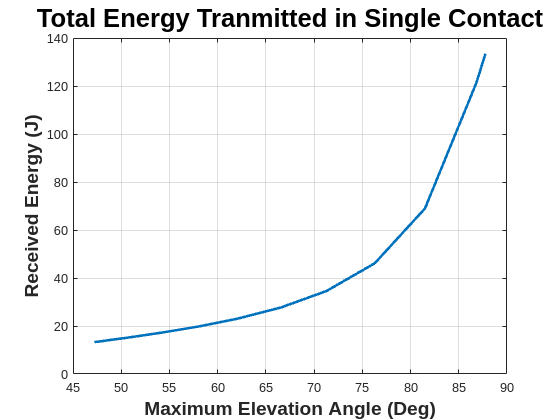


figure;

plot(max_elevation_angle, total_received_energy_vec,'LineWidth',2)
title('Total Energy Tranmitted in Single Contact','FontSize',20,'FontWeight','bold')
ylabel('Received Energy (J)','FontSize',15,'FontWeight','bold')
xlabel('Maximum Elevation Angle (Deg)','FontSize',15,'FontWeight','bold')
grid on


$$\begin{array}{l}
E_{\textrm{transmitted}} =\int_{t_{\textrm{start}} }^{t_{\textrm{end}} } \eta_{\textrm{BCE}} \left(\theta_{\textrm{elevation}} \right)P_{\textrm{in}} \;\textrm{dt}\approx \sum_{t_{\textrm{start}} }^{t_{\textrm{end}} } \eta_{\textrm{BCE}} {\left(\theta_{\textrm{elevation}} \right)P}_{\textrm{in}} \Delta t\\
E:\textrm{Total}\;\textrm{Transmitted}\;\textrm{Energy}\;\left\lbrack J\right\rbrack \\
P_{\textrm{in}} :\textrm{Transmitted}\;\textrm{Energy}\;\textrm{from}\;\textrm{Payload}-\textrm{Constant}:675\textrm{kW}\\
\eta_{\textrm{BCE}} :\textrm{Power}\;\textrm{transmisstion}\;\textrm{effieiccy}-\;\textrm{Function}\;\textrm{of}\;\textrm{Elev}\;\textrm{Angle}\;\left\lbrack \deg \right\rbrack \\
\theta_{\textrm{elevation}} :\textrm{Elevation}\;\textrm{Angle}\;\left\lbrack \deg \right\rbrack \\
\Delta t:\textrm{Step}\;\textrm{time}-\textrm{Constant}:\;0\ldotp 1\;\textrm{seconds}
\end{array}$$
